# Rad229 - Lecture 4:  Extended Phase Graphs

## lec4_01.m:  180 pulses

Note that these are "special" pulses that just swap states, so are relatively easy, as well as intuitive:

% Lecture 4, Example 01
% 
% Simple image reconstruction in matlab
%
[Q,R] = epg_rf(epg_m0(), pi,0); disp('Rotation about Mx:'); disp(R);

Rotation about Mx:
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 + 0.0000i  -1.0000 + 0.0000i



[Q,R] = epg_rf(epg_m0(), pi,pi/2); disp('Rotation about My:'); disp(R);

Rotation about My:
   0.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 - 0.0000i
  -1.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -1.0000 + 0.0000i



## lec4_02.m:  Spin-Echo with 180°x Pulses

% Lecture 4, Example 02
% 
% Simple image reconstruction in matlab
%
disp('-- Spin Echo with 180x pulses --')

-- Spin Echo with 180x pulses --


Q = epg_m0(2); disp('Equilibrium: '); disp(Q)

Equilibrium: 
     0     0
     0     0
     1     0



T1 = 195; T2=95; T=10;     % Chosen for E1=0.95, E2=0.9
Q = epg_relax(Q,T1,T2,T);
Q = epg_rf(Q,pi/2,pi/2); disp('Excitation: '); disp(Q)

Excitation: 
   1.0000 - 0.0000i   0.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i



Q = epg_relax(epg_grad(Q,1),T1,T2,T); disp('Pre-180: '); disp(Q)

Pre-180: 
   0.0000 + 0.0000i   0.9001 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0500 + 0.0000i   0.0000 + 0.0000i



Q = epg_rf(Q,pi,0); disp('Post-180'); disp(Q)

Post-180
   0.0000 - 0.0000i   0.0000 - 0.0000i
   0.0000 + 0.0000i   0.9001 - 0.0000i
  -0.0500 + 0.0000i  -0.0000 - 0.0000i



Q = epg_relax(epg_grad(Q,1),T1,T2,T); disp('1st Spin Echo: '); disp(Q)

1st Spin Echo: 
   0.8102 + 0.0000i   0.0000 - 0.0000i
   0.8102 - 0.0000i   0.0000 + 0.0000i
   0.0025 + 0.0000i  -0.0000 - 0.0000i



Q = epg_relax(epg_grad(Q,1),T1,T2,T); disp('Pre-180: '); disp(Q)

Pre-180: 
   0.0000 + 0.0000i   0.7292 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0524 + 0.0000i  -0.0000 - 0.0000i



Q = epg_rf(Q,pi,0); disp('Post-180'); disp(Q)

Post-180
   0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0000 + 0.0000i   0.7292 + 0.0000i
  -0.0524 + 0.0000i   0.0000 + 0.0000i



Q = epg_relax(epg_grad(Q,1),T1,T2,T); disp('2nd Spin Echo: '); disp(Q)

2nd Spin Echo: 
   0.6564 - 0.0000i   0.0000 - 0.0000i
   0.6564 + 0.0000i   0.0000 + 0.0000i
   0.0002 + 0.0000i   0.0000 + 0.0000i



## lec4_03 and lec4_04

These are animation examples.  They will show a spin-echo formation using 180° and 130° refocusing pulses.  These are not shown in Matlab Live.  If you setup variables for epg_saveframe, you can use this to make movie clips.

## lec4_05.m

This is the example with a stimulated echo and spin echo from the lecture.

## lec4_06.m

A nice compact way to look at all the states:

% Lecture 4, Example 06
% 
% Display EPG states with real coefficients
Q = ones(3,4);
Q(3,2:end) = Q(3,2:end)/2

Q =     1.0000    1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000    1.0000
    1.0000    0.5000    0.5000    0.5000


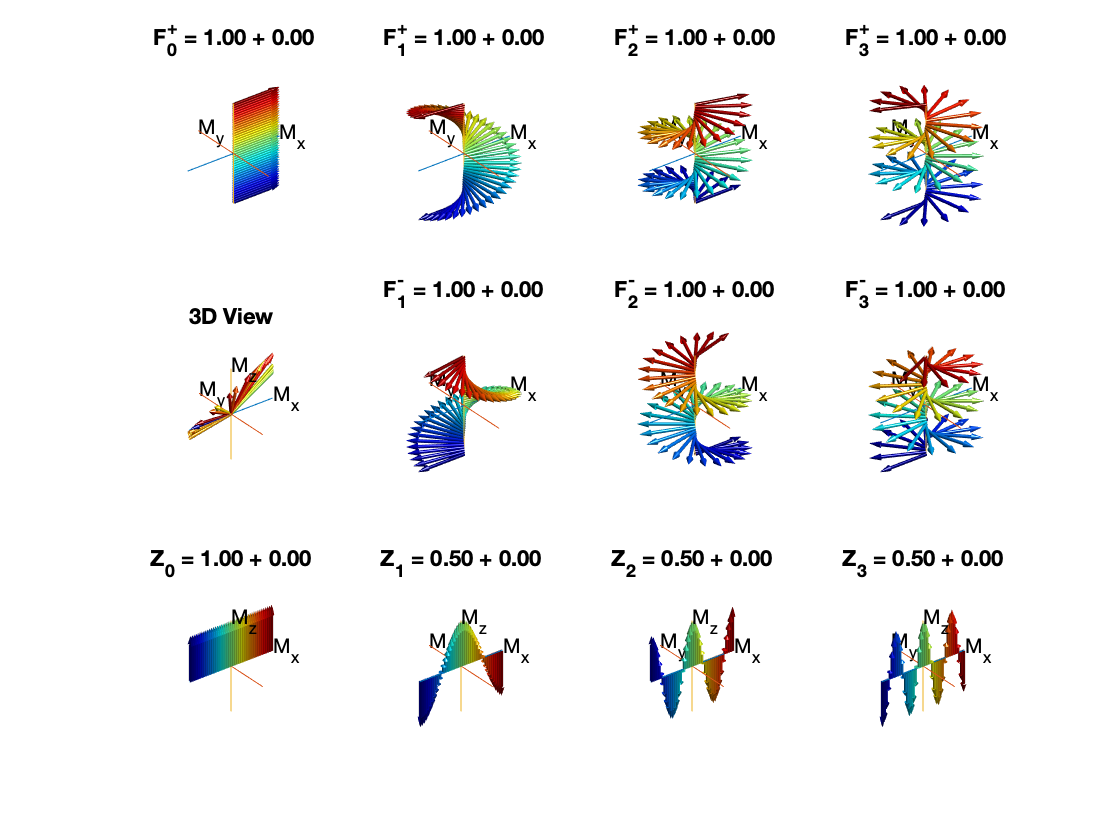

epg_show(Q,[],[],43,1);

Try multiplying Q(:,2:end) by i

### In Class Exercises:

Look at the EPG functions in the code directory:

help epg

 
 	epg - Extended Phase Graph Analysis Functions
 
 	These functions allow pulse sequence analysis
 	using the Extended Phase Graph (epg) techniques - 
 	see Hennig, Weigel, and other articles.
 
 	epg is based on dephased states, often called
 	F+, F- and Z, where the "dephasing order" indicates
 	how many cycles of dephasing the spins have undergone.
 
 	** Note some "show" functions use the arrow3D package, which
 	must be downloaded and installed separately for better looking
 	movies.
 
 	FUNCTIONS:	(help epg_xx to see syntax)
 
 	epg_rf	- propagate states through an RF pulse.
 	epg_grad - propagate through positive gradient only.
 	epg_mgrad - propagate through negative gradient only.
 	epg_grelax - propagate through relaxation and diffusion 
 			with or without a constant gradient.
 	epg_plot - simple plot of F,Z states.
 	epg_plotcomp - plot of Mz,My,Mz components across a voxel
 	epg_plot3Df - 3D plot of F states as spins in 

Try a simple simulation:

Q = epg_m0;        % Equilibrium
Q = epg_rf(Q);     % Excitation

epg_rf defaulting to M0 with alpha=1.5708, phi=0


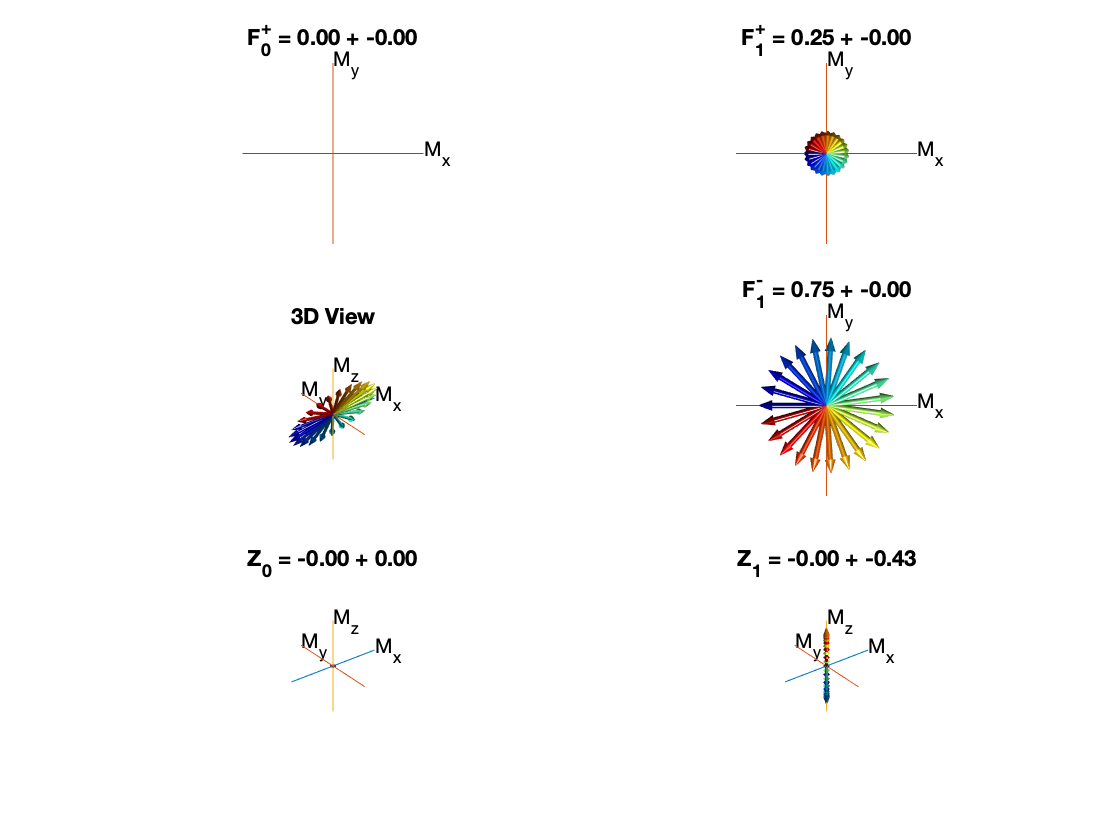

Q = epg_grad(Q);   % Gradient
Q = epg_rf(Q,2*pi/3,0);   % 120 refocusing
epg_show(Q);       % Show states

disp('State Matrix');

State Matrix


disp(Q);

   0.0000 - 0.0000i   0.2500 - 0.0000i
   0.0000 + 0.0000i   0.7500 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 - 0.4330i

